## Backend

load RawData\1T-TaS2(DWN)\LinearDWN(0_0_1).mat
ifload RawData\1T-TaS2(DWN)\TTDWmap.mat

ans = "already"

load RawData\1T-TaS2(DWN)\quickTTDWmap.mat
load RawData\1T-TaS2(DWN)\DWsampling(1_0_0).mat

addpath("Scripts\1T-TaS2(DWN)\2026.09.13_1TT_dw_prfl\DV\")
G = TTDWNmap.dt.Gs(:,:,:,1);
V = TTDWNmap.dt.V;
a = Gread(G,V);

b =   Gshow with properties:

         G: [400×400×2001 double]
         V: [-1 -0.9990 -0.9980 -0.9970 -0.9960 -0.9950 -0.9940 -0.9930 -0.9920 -0.9910 -0.9900 -0.9890 -0.9880 -0.9870 -0.9860 -0.9850 -0.9840 -0.9830 -0.9820 -0.9810 -0.9800 -0.9790 -0.9780 -0.9770 -0.9760 -0.9750 -0.9740 -0.9730 … ] (1×2001 double)
    n_prfl: 100


function draw_prfl_on_topo(p0,vec)
hold on
quiver(p0(1),p0(2),vec(1),vec(2),1,'r','LineWidth',1,'MaxHeadSize',.2) % 0: 스케일 비활성화
hold off
end

function draw6_prfls(p0ss,basis)
cnt = 0
for idir = 1:3
    vec = basis(idir,:)
    for iex = 1:2
        cnt = cnt + 1
        p0 = p0ss(:,iex,idir)
        draw_prfl_on_topo(p0, vec);
        text(p0(1),p0(2),string(cnt),"Color",'g')
    end
end
end



function prfl = get_ldos_prfl(G,p0,p1,n)
%GET_LDOS_PRFL Extract an LDOS profile along a 2D line for each z-slice
%  prfl = GET_LDOS_PRFL(G,p0,p1,n)
%    G   : 3D array (rows = y, cols = x, pages = z)
%    p0  : [x0,y0] start in array indices (can be non-integer)
%    p1  : [x1,y1] end
%    n   : number of sample points along the line
%  prfl: n-by-size(G,3) matrix. row i is profile along z at position i.

% input checks
if nargin < 4, error('Usage: get_ldos_prfl(G,p0,p1,n)'); end
assert(ndims(G)==3, 'G must be a 3D array');
p0 = double(p0(:).'); p1 = double(p1(:).');
assert(numel(p0)==2 && numel(p1)==2, 'p0 and p1 must be [x,y]');

% line sample positions (x,y) in array coordinates (cols, rows)
xi = linspace(p0(1), p1(1), n).';
yi = linspace(p0(2), p1(2), n).';

[rows, cols, nz] = size(G);
prfl = nan(n, nz);

% use interp2 on each z-slice; grid is X=1:cols, Y=1:rows
X = 1:cols; Y = 1:rows;
for k = 1:nz
    V = G(:,:,k);
    % interp2 expects XI,YI of same size; provide vectors of same length
    prfl(:,k) = interp2(X, Y, V, xi, yi, 'linear', NaN);
end
end

idt = 1

idt = 1

iex = 1

iex = 1

idir = 1

idir = 1

scl = 15

scl = 15

p0 = origins(:,iex,idir,idt)

p0 =    130
   100


basis = lDWN.dt(idt).basis

basis =     8.5255    2.9398
    7.0658   -6.4484
    1.4596    9.3882
   15.5913   -3.5087
    9.9851   12.3280
   -5.6062   15.8366


vec = basis(idir,:)

vec =     8.5255    2.9398


p1 = p0 + transpose(vec*scl)

p1 =   257.8820
  144.0963


n= 100

n = 100

prfl = get_ldos_prfl(G,p0,p1,n)

prfl =    -5.0704   -4.2287   -3.3869   -2.5483   -1.7053   -0.8662   -0.5991   -0.3326   -0.0651    0.2068    0.4786    0.7539    1.0305   -0.1421   -1.3125   -2.4793   -3.6502   -4.8178   -4.6350   -4.4556   -4.2768   -4.1023   -3.9314   -3.7627   -3.5953   -2.8128   -2.0347   -1.2594   -0.4819    0.2918    0.2891    0.2887    0.2854    0.2815    0.2819    0.2777    0.2758    0.2748    0.2760    0.2767    0.2742    0.2739    0.2715    0.2690    0.2682    0.2686    0.2661    0.2685    0.2682    0.2693
   -4.6055   -3.8237   -3.0417   -2.2624   -1.4806   -0.7003   -0.4336   -0.1654    0.1039    0.3758    0.6473    0.9231    1.2002    0.1364   -0.9259   -1.9845   -3.0462   -4.1059   -3.9566   -3.8109   -3.6674   -3.5270   -3.3895   -3.2557   -3.1237   -2.4234   -1.7264   -1.0317   -0.3365    0.3554    0.3532    0.3509    0.3483    0.3445    0.3436    0.3410    0.3385    0.3377    0.3369    0.3355    0.3330    0.3308    0.3257    0.3221    0.3181    0.3153    0.3112    0.3089    0.3067  

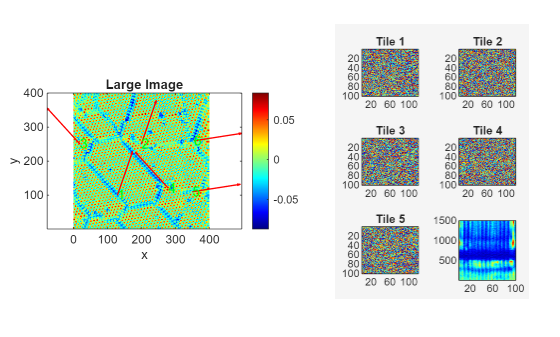

imagesc(prfl(:,400:1900).')
colormap('jet')
axis xy

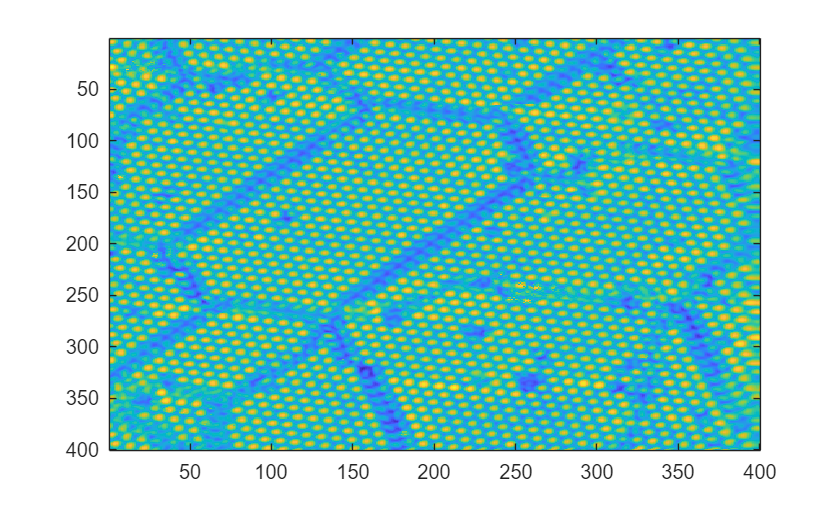

imagesc(Z)

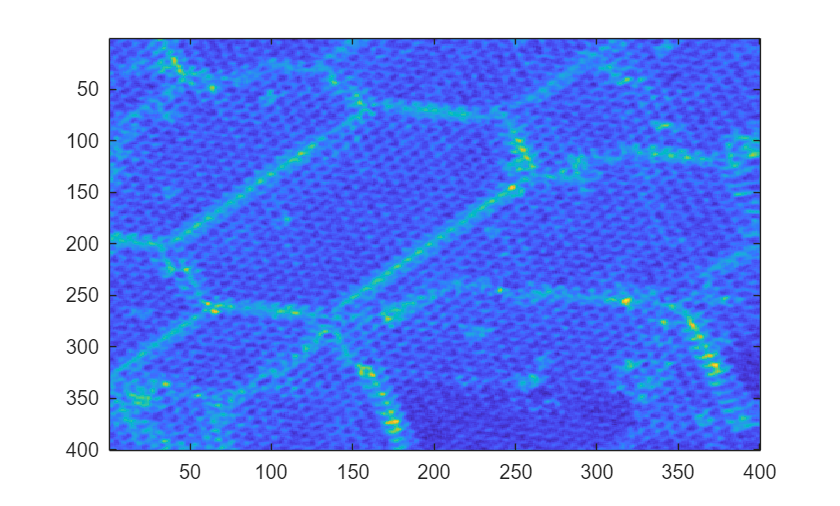

imagesc(G(:,:,1200))

mod(3,2)

ans = 1

origins = ones(2,2,3,3)*200;% 1st(x,y),2nd:two examples, 3rd:directions, 4th: 3 data
origins(:,1,:,:) = 100;
origins(:,1,1,1) = [130,100];
origins(:,2,1,1) = [200,250];
origins(:,1,2,1) = [20,250];
origins(:,2,2,1) = [280,120];
origins(:,1,3,1) = [350,110];
origins(:,2,3,1) = [355,260];

## Frontend

idt = 1

idt = 1

scl = 15

scl = 15

Z = TTDWNmap.dt.Zs(:,:,idt);
G = TTDWNmap.dt.Gs(:,:,:,idt);
%Z = G(:,:,1200)
basis = lDWN.dt(idt).basis;
basis = basis(:,[2,1])

basis =     2.9398    8.5255
   -6.4484    7.0658
    9.3882    1.4596
   -3.5087   15.5913
   12.3280    9.9851
   15.8366   -5.6062


p0ss = origins(:,:,:,idt);

% Example: left large image, right 3x2 small subpanels
% close existing figures before creating new one
if ~isempty(findall(0,'Type','figure'))
    close all force
end
f = figure('Name','Left big image / Right 3x2','Color','w');

% Top-level layout: 1 row, 2 columns (left large, right small grid)
tl = tiledlayout(f,1,2,'TileSpacing','compact','Padding','compact');

% Left: one big axes filling left tile
axL = nexttile(tl,1);
imagesc(Z)
colormap(gray)                     % 그레이 스케일
axis image                         % 종횡비 유지, 픽셀 비율 1:1
axis xy                            % 이미지 좌표계(원점 상단-left, y가 아래로 증가)
colorbar
xlabel('x'); ylabel('y');
title(axL,'Large Image');
draw6_prfls(p0ss,basis*scl)

cnt = 0

vec =    44.0963  127.8820


cnt = 1

p0 =    130
   100


cnt = 2

p0 =    200
   250


vec =   -96.7267  105.9876


cnt = 3

p0 =     20
   250


cnt = 4

p0 =    280
   120


vec =   140.8230   21.8944


cnt = 5

p0 =    350
   110


cnt = 6

p0 =    355
   260



% Right: nested tiledlayout with 3 rows x 2 cols
% Use nexttile to occupy the right tile, then create a tiledlayout inside it
rightContainer = nexttile(tl,2);
% Replace rightContainer axes with an empty axes so we can position the nested layout
cla(rightContainer); axis(rightContainer,'off');

% Create nested tiledlayout positioned to match the right tile
pos = rightContainer.Position;
% Create a new invisible parent uipanel to host the nested tiles (keeps positioning stable)
p = uipanel(f,'Units','normalized','Position',pos,'BorderType','none');

innerTL = tiledlayout(p,3,2,'TileSpacing','compact','Padding','compact');

% Fill the 6 inner tiles
iexs = [1,2,1,2,1,2]

iexs =      1     2     1     2     1     2


idirs = [1,1,2,2,3,3]

idirs =      1     1     2     2     3     3


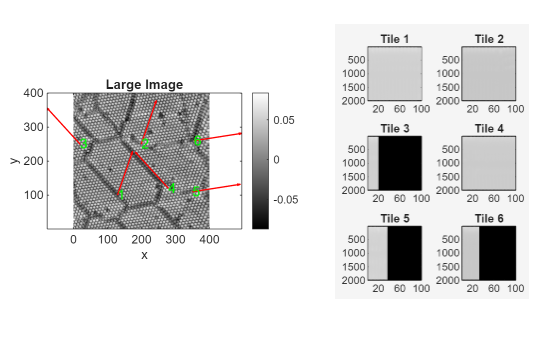

p0 =    130
   100


p1 =   174.0963
  227.8820


p0 =    200
   250


p1 =   244.0963
  377.8820


p0 =     20
   250


p1 =   -76.7267
  355.9876


p0 =    280
   120


p1 =   183.2733
  225.9876


p0 =    350
   110


p1 =   490.8230
  131.8944


p0 =    355
   260


p1 =   495.8230
  281.8944


for k = 1:6
    ax = nexttile(innerTL,k);
    iex = iexs(k);
    idir = idirs(k);
    p0 = origins(:,iex,idir,idt)
    vec = basis(idir,:);
    p1 = p0 + transpose(vec*scl)
    prfl = get_ldos_prfl(G,p0,p1,n);
    imagesc(prfl(:,:).');
    title(ax,sprintf('Tile %d',k));
    caxis(ax, [min(prfl(:)), max(prfl(:))]);
end


% Optional: adjust relative widths (make left wider)
